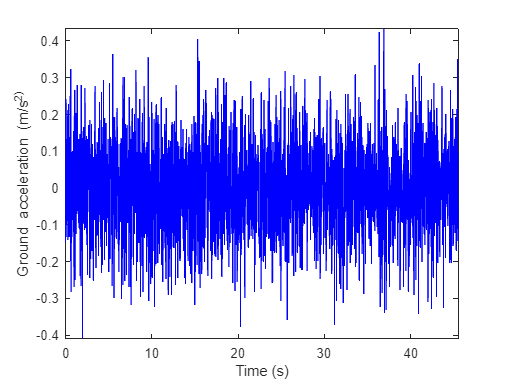

% Existing code for ground acceleration generation
clearvars; close all; clc;

f = linspace(0,45,2048); % frequency vector
zeta = 0.5; % bandwidth of the earthquake excitation.
sigma = 0.5; % standard deviation of the excitation.
fn = 20; % dominant frequency of the earthquake excitation (Hz).
T90 = 1; % value of the envelop function at 90 percent of the duration.
eps = 0.9; % normalized duration time when ground motion achieves peak.
tn = 50; % duration of ground motion (seconds).

% Function call to generate ground acceleration
[y, t] = seismSim(sigma, fn, zeta, f, T90, eps, tn); 
% y: acceleration record
% t: time

% Plot the generated ground acceleration
figure;
plot(t, y, 'b');
xlabel('Time (s)');
ylabel('Ground acceleration (m/s^2)');
axis tight;

set(gcf, 'color', 'w');

% Step 1: Normalize the signal for audio playback
y_normalized = (y - min(y)) / (max(y) - min(y));  % Normalize to 0-1
y_audio = y_normalized * 2 - 1; % Scale to range [-1, 1] for audio playback

% % Calculate the maximum allowable gain to prevent clipping
% max_gain = 1 / max(abs(y_audio)); 
% disp(['Maximum allowable gain without clipping: ', num2str(max_gain)]);
% 
% % Set the gain value
% gain = max_gain; % or use a smaller value if clipping is acceptable

% Step 2: Increase amplitude of the signal using a gain factor
gain = 125; % Set the gain factor (>1 increases amplitude, <1 decreases)
y_amplified = y_audio * gain;

% Step 3: Resample the signal to increase playback duration
desired_duration = 10; % Set the desired playback duration in seconds
fs = 44100; % Standard audio sampling rate (44.1 kHz)
original_duration = length(t) / (length(t) / tn); % Original duration of the signal
resample_factor = desired_duration / original_duration; % Resampling factor

% Resample the signal
y_resampled = resample(y_amplified, round(fs * desired_duration), length(y_amplified)); 

% Step 4: Clip the signal to prevent distortion
y_resampled_clipped = max(min(y_resampled, 1), -1); % Clip the signal to [-1, 1]

% Step 5: Play the waveform using MATLAB's sound function
disp('Playing the amplified waveform on system audio...');

Playing the amplified waveform on system audio...


sound(y_resampled_clipped, fs); % Play the audio waveform
pause(desired_duration); % Pause to allow playback to complete
disp('Playback complete.');

Playback complete.



% Optional: Save the audio as a .wav file
audiowrite('ground_acceleration_amplified.wav', y_resampled_clipped, fs);
disp('Amplified audio waveform saved as "ground_acceleration_amplified.wav".');

Amplified audio waveform saved as "ground_acceleration_amplified.wav".



% Compute RMS power of the amplified signal
P_signal = rms(y_resampled_clipped).^2; % Power of the signal

% Estimate noise using a high-pass filter (assume noise is above 45 Hz)
[b, a] = butter(4, 45/(fs/2), 'high'); % 4th-order Butterworth filter
y_noise = filtfilt(b, a, y_resampled_clipped); % Extract noise component

% Compute RMS power of noise
P_noise = rms(y_noise).^2;

% Compute noise level in dB
noise_dB = 10 * log10(P_noise / P_signal);

% Display results
disp(['Noise level in dB: ', num2str(noise_dB)]);

Noise level in dB: -1.7023
